# **Point Cloud Real Troubleshooting**

**Detector**

load("DetectorARMChallenge.mat");

**Arquivos**

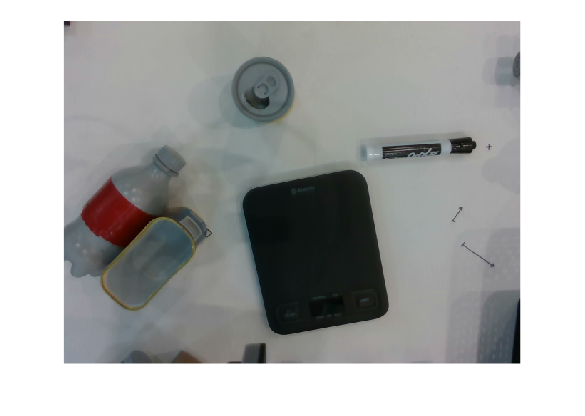

colorImage = imread("20.png"); %COR
imshow(colorImage);

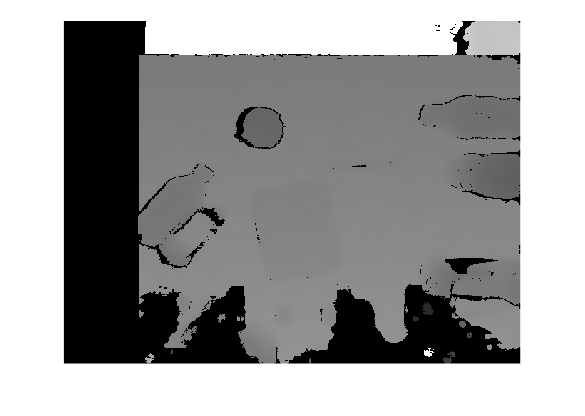

depthImage = imread("20_d.png"); %DEPTH
imshow(depthImage);

**Parâmetros**

larguraZ = 0.0002; % Espessura do plano recortado
tol = 100; %Tolerancia de cor
K = 2e-1; %Parâmetro de escala
downsamplesize = 0.01; %Parâmetro do downsample
Indist = 0.1; %Parâmetro do ICP

% Parâmetros do modelo 
r = 0.012/K;       % raio        
h = 0.055/K;       % altura    
n_theta = 60;      % número de pontos ao redor do círculo
n_height = 40;     % número de camadas ao longo da altura

% Configuração da câmera
focalLength      = [600, 600]; %Define a escala pela qual as 
% coordenadas homogêneas são extendidas para forma
principalPoint   = size(depthImage,[1,2])/2;
imageSize        = size(depthImage,[1,2]);
depthScaleFactor = 5e2*K; %Reescala a nuvem de pontos, ajudando no processamento de imagens
% menores. É necessário para achar distâncias reais.
maxCameraDepth   = 100; %serve de algo?

intrinsics = cameraIntrinsics(focalLength,principalPoint,imageSize);

**1.Recorte da Imagem da Câmera**

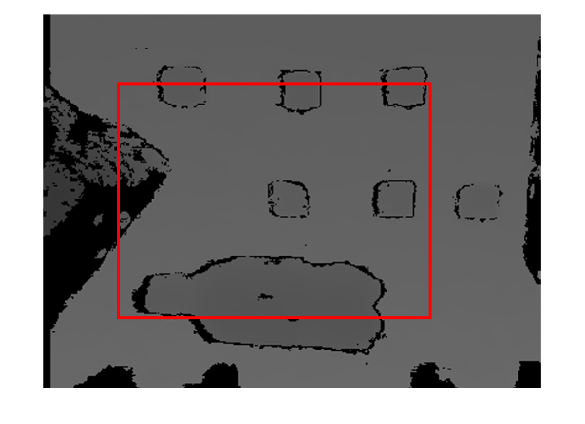

img = depthImage;
[imgH, imgW, ~] = size(img);
imgM = imresize(img,1.596);
roi = [155,143, imgW, imgH];
recorte = imcrop(imgM, roi);

figure;
imshow(imgM);
hold on;
rectangle('Position', roi, 'EdgeColor', 'r', 'LineWidth', 2);
hold off;

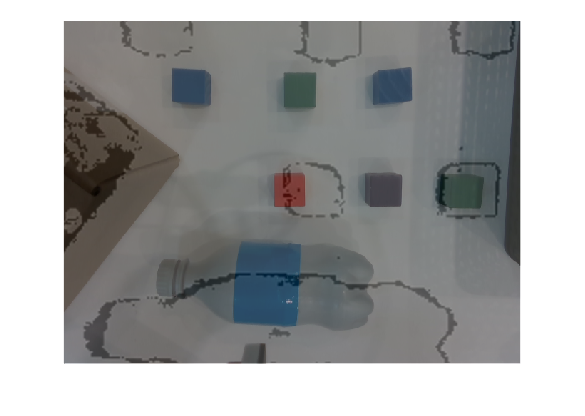


figure;
imshow(colorImage); 
hold on;
q = imshow(recorte);
set(q, 'AlphaData', 0.5); % 50% de opacidade
hold off;


recorte = im2gray(recorte);
[rows, cols, ~] = size(colorImage);
recorte = imresize(recorte, [rows cols]);

depthImage = recorte;

**2.Geração da Point Cloud**

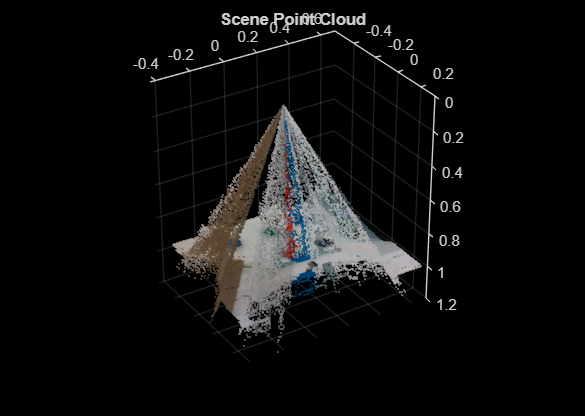

ptCloud = pcfromdepth(recorte,depthScaleFactor, intrinsics, ...
          ColorImage=colorImage, DepthRange=[0 maxCameraDepth]);

pcshow(ptCloud,'VerticalAxis','Z','VerticalAxisDir','Down');
title("Scene Point Cloud");

**3.Detecting Objects (Function)**

function [objetosComPlano, objetosSemPlano, objetosLabel] = extrairObjetosDeDeteccoes(ptCloudOrg, bboxes, ...
    labels)

    [rows, cols, ~] = size(ptCloudOrg.Location);
    xyzVec = reshape(ptCloudOrg.Location, [], 3);
    rgbVec = reshape(ptCloudOrg.Color, [], 3);

    objetosComPlano = {};
    objetosSemPlano = {};
    objetosLabel = {};

    for i = 1:size(bboxes, 1)
        bbox = round(bboxes(i, :));  % [x, y, w, h]
        x1 = max(1, min(bbox(1), cols));
        x2 = max(1, min(bbox(1) + bbox(3) - 1, cols));
        y1 = max(1, min(bbox(2), rows));
        y2 = max(1, min(bbox(2) + bbox(4) - 1, rows));

        mask = false(rows, cols);
        mask(y1:y2, x1:x2) = true;
        linearIdx = find(mask);

        xyz = xyzVec(linearIdx, :);
        rgb = rgbVec(linearIdx, :);

        % Remove NaNs
        validIdx = ~any(isnan(xyz), 2);
        pt = pointCloud(xyz(validIdx, :), 'Color', rgb(validIdx, :));

        % Armazena o ponto (sem remover plano)
        objetosComPlano{end+1} = pt;
        objetosSemPlano{end+1} = pt;

        % Armazena o rótulo correspondente
        objetosLabel{end+1} = labels(i);
    end
end

**Detecting Objects (Code)**

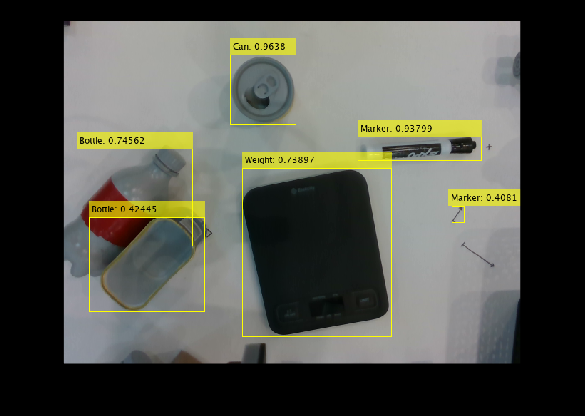

[bboxes, scores, labels] = detect(Detector, colorImage);

%Threshold de overlap
[bboxes, scores, selectedIdx] = selectStrongestBbox(bboxes, scores, ...
    'OverlapThreshold', 0.5);
labels = labels(selectedIdx);

labelsWithScores = string(labels) + ": " + string(scores);
imTested = insertObjectAnnotation(colorImage, "rectangle", bboxes, labelsWithScores);
imshow(imTested);

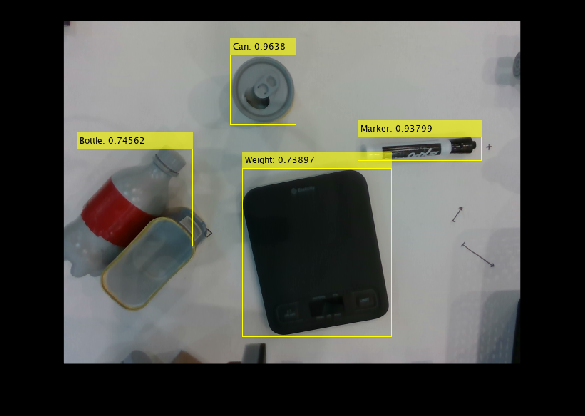


%Threshold de score
idxValidos = scores >= 0.7;
bboxes = bboxes(idxValidos, :);
scores = scores(idxValidos);
labels = labels(idxValidos);

labelsWithScores = string(labels) + ": " + string(scores);
imTested = insertObjectAnnotation(colorImage, "rectangle", bboxes, labelsWithScores);
imshow(imTested);

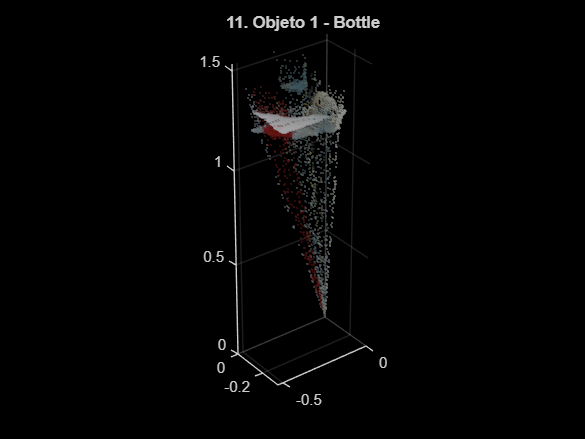

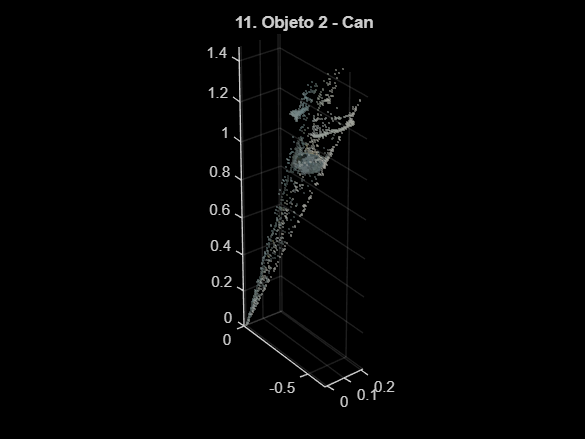

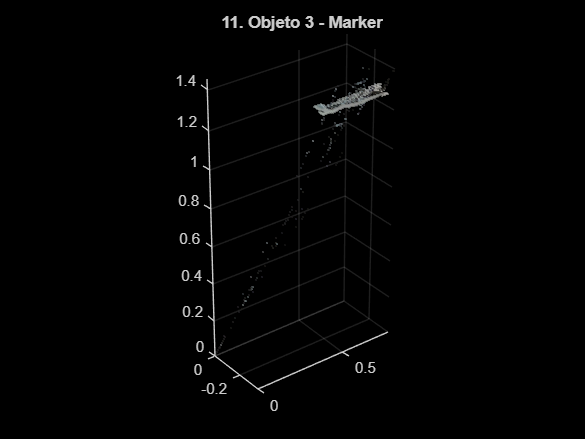

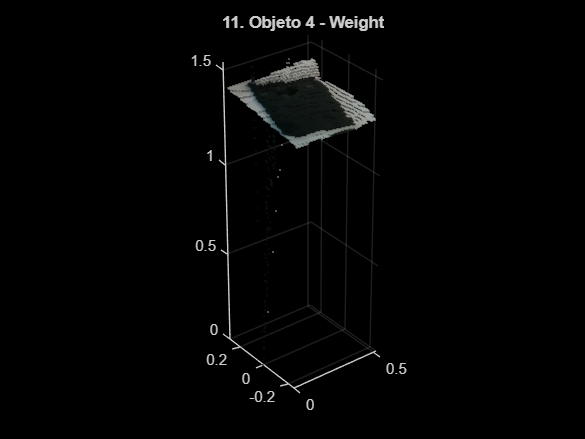


[objCom, objSem, objLab] = extrairObjetosDeDeteccoes(ptCloud, bboxes,labels);

Tmatrix = cell(1, numel(objSem));
Tmodel = cell(1, numel(objSem));

for k = 1:numel(objSem)
    figure;
    pcshow(objSem{k});
    title(sprintf("11. Objeto %d - %s", k, string(labels(k))));
end

**4.Object Models (Function)**

function ptCloud = cubeCloud(L, n)
    h = L / 2;
    lin = linspace(-h, h, n);
    pontos = [];
    
    [x, y] = meshgrid(lin, lin);
    z1 = -h * ones(size(x));
    z2 =  h * ones(size(x));
    %pontos = [pontos; [x(:), y(:), z1(:)]];
    pontos = [pontos; [x(:), y(:), z2(:)]];
    
    [y, z] = meshgrid(lin, lin);
    x1 = -h * ones(size(y));
    x2 =  h * ones(size(y));
    pontos = [pontos; [x1(:), y(:), z(:)]];
    pontos = [pontos; [x2(:), y(:), z(:)]];
    
    [x, z] = meshgrid(lin, lin);
    y1 = -h * ones(size(x));
    y2 =  h * ones(size(x));
    pontos = [pontos; [x(:), y1(:), z(:)]];
    pontos = [pontos; [x(:), y2(:), z(:)]];
    
    pontos = unique(pontos, 'rows');
    
    ptCloud = pointCloud(pontos);
end

**Object Models (Code)**

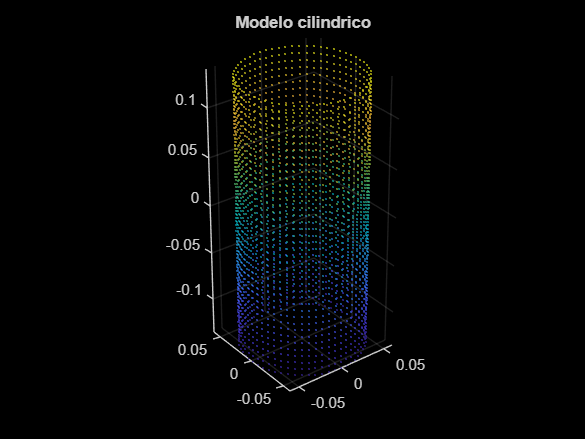

% Geração de coordenadas cilíndricas
theta = linspace(0, 2*pi, n_theta);
z1 = linspace(-h/2, h/2, n_height);

[Theta, Z] = meshgrid(theta, z1);
X = r * cos(Theta);
Y = r * sin(Theta);

% Vetores 1D para criar matriz N×3
xyz = [X(:), Y(:), Z(:)];

% Criar pointCloud
PcModeloCil = pointCloud(xyz);
pcshow(PcModeloCil);
title("Modelo cilindrico");

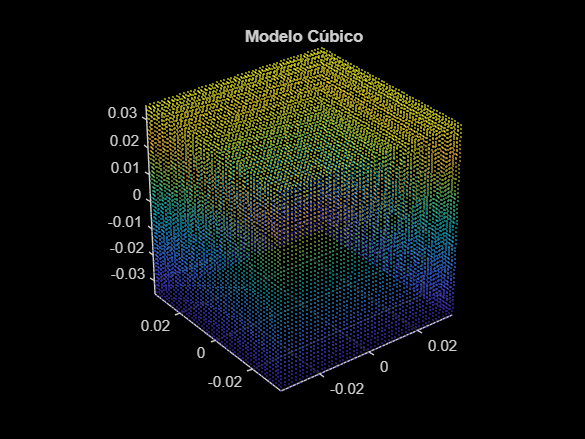


L = 0.07;
n = 50;
PcModeloCube = cubeCloud(L, n);

figure;
pcshow(PcModeloCube);
grid on;
title("Modelo Cúbico");

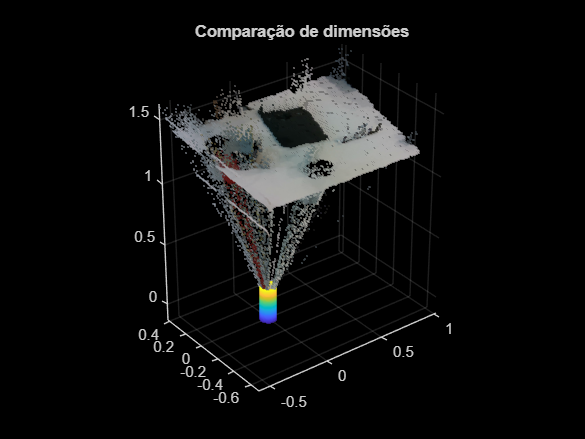


figure;
pcshow(ptCloud);
hold on;
pcshow(PcModeloCube);
pcshow(PcModeloCil);
title("Comparação de dimensões");
hold off;

**5. Object Treatment (Functions)**

**identificarPlanoHorizontalMaisDenso**

function [zPlano, indicesPlano, ptPlano] = identificarPlanoHorizontalMaisDenso(ptCloud, larguraZ)

    % Extrai pontos válidos
    pts = ptCloud.Location;
    pts = reshape(pts, [], 3);
    pts = pts(~any(isnan(pts), 2), :);  % remove NaNs

    % Extrai componente Z
    z = pts(:,3);

    % Define os bins de Z
    zMin = min(z);
    zMax = max(z);
    edges = zMin:larguraZ:zMax;

    % Conta quantos pontos caem em cada faixa de Z
    [counts, ~, binIdx] = histcounts(z, edges);

    % Encontra bin com mais pontos
    [~, maxBin] = max(counts);

    % Define limites Z do plano mais denso
    zLow = edges(maxBin);
    zHigh = edges(maxBin+1);

    % Seleciona pontos que estão dentro da faixa
    indicesPlano = find(z >= zLow & z <= zHigh);
    planoPts = pts(indicesPlano, :);

    color = [];
    if ~isempty(ptCloud.Color)
        cor = reshape(ptCloud.Color, [], 3);
        corPlano = cor(indicesPlano, :);
        color = corPlano;
    end

    if isempty(color)
        ptPlano = pointCloud(planoPts);
    else
        ptPlano = pointCloud(planoPts, "Color", color);
    end

    zPlano = mean(planoPts(:,3));
end

**removerPontosCorProximaPlano**

function [ptFiltrada, corMedia] = removerPontosCorProximaPlano(ptCloud, ptPlano, tolerancia)

    if isempty(ptCloud.Color) || isempty(ptPlano.Color)
        error("Ambas as pointClouds devem conter dados de cor.");
    end

    corPlano = reshape(ptPlano.Color, [], 3);
    corTotal = reshape(ptCloud.Color, [], 3);

    corMedia = mean(double(corPlano), 1);

    distCor = sqrt(sum((double(corTotal) - corMedia).^2, 2));

    idxMantidos = find(distCor > tolerancia);
    ptFiltrada = select(ptCloud, idxMantidos);
end

**Object Treatment (Code)**

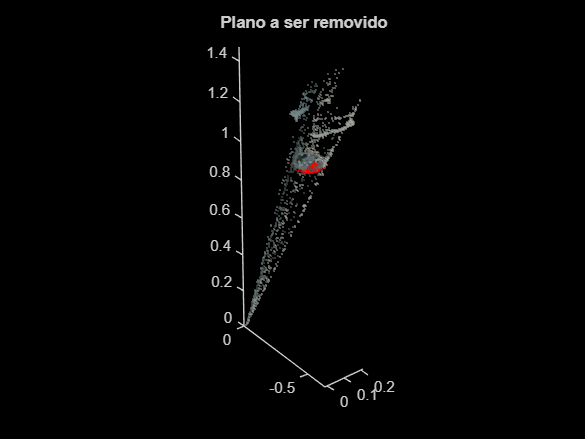

k = 2;
PtCloudObj1 = objSem{k};

label = string(objLab{k});

if label == "Bottle" || label == "Can"
    PcModeloICP = PcModeloCil;
elseif label == "Weight"
else
    PcModeloICP = PcModeloCube;
end
    
%Remoção do plano de chão
[zPlano, indicesPlano, ptPlano] = identificarPlanoHorizontalMaisDenso(PtCloudObj1, larguraZ);

indicesRestantes = setdiff(1:PtCloudObj1.Count, indicesPlano);
ptSemPlano = select(PtCloudObj1, indicesRestantes);

corUnica = uint8(repmat([255, 0, 0], ptPlano.Count, 1));
ptPlano.Color = corUnica;
figure;
hold on;
pcshow(ptPlano)
pcshow(ptSemPlano)
title("Plano a ser removido");
hold off;

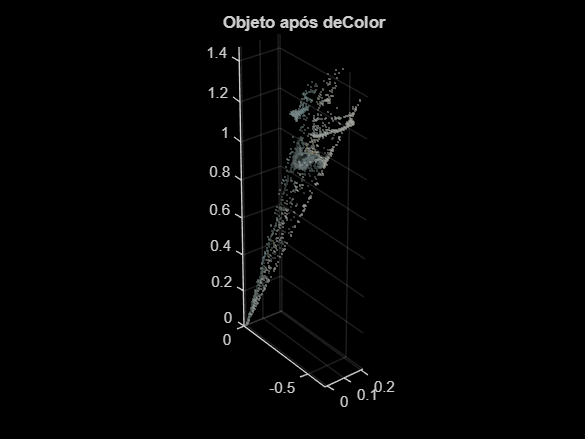


%Remoção de outliers do chão
[ptSemCor, ~] = removerPontosCorProximaPlano(ptSemPlano, ptPlano, tol);
PcObjectICP = pcdenoise(ptSemCor);
pcshow(ptSemCor);
title("Objeto após deColor");

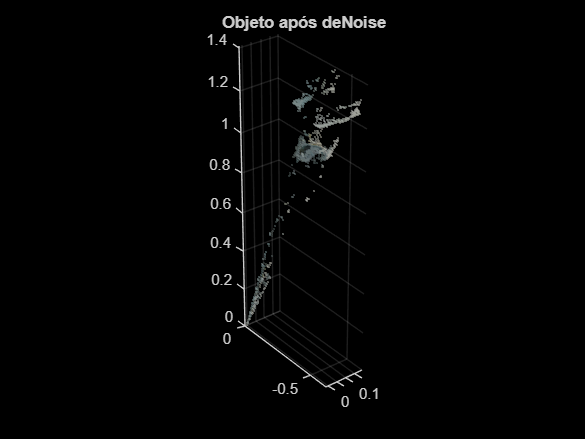


pcshow(PcObjectICP);
title("Objeto após deNoise");

**>> Object Treatment***********

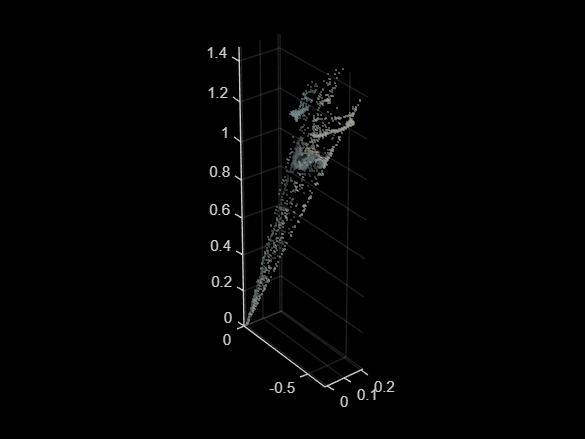

k = 2;
PtCloudObj1 = objSem{k};

label = string(objLab{k});

if label == "Bottle" | label == "Can"
    PcModeloICP = PcModeloCil;
elseif label == "Weight"
else
    PcModeloICP = PcModeloCube;
end

PcObjectICP = pcdenoise(PcObjectICP);
pcshow(ptSemCor);

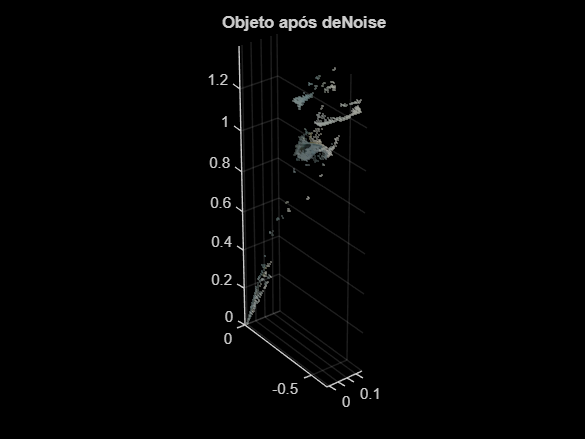

pcshow(PcObjectICP);
title("Objeto após deNoise");

**6. ICP (Translado antes)**

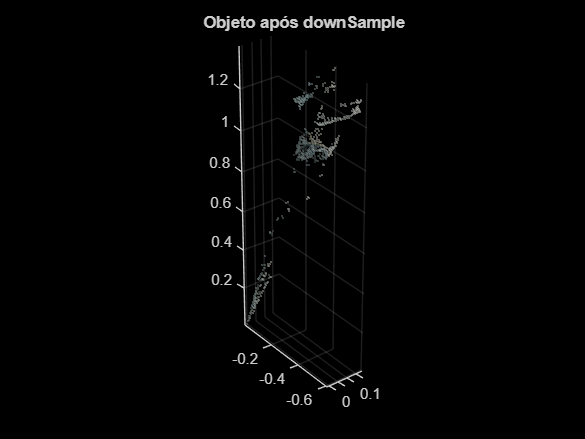

%Cálculo do centróide e do chute inicial
initTform = rigid3d(eye(3), mean(PtCloudObj1.Location));
PcModeloT = pctransform(PcModeloICP,initTform);

%Uso do ICP
PcObjectICP = pcdownsample(PcObjectICP,'gridAverage',downsamplesize);
pcshow(PcObjectICP);
title("Objeto após downSample");

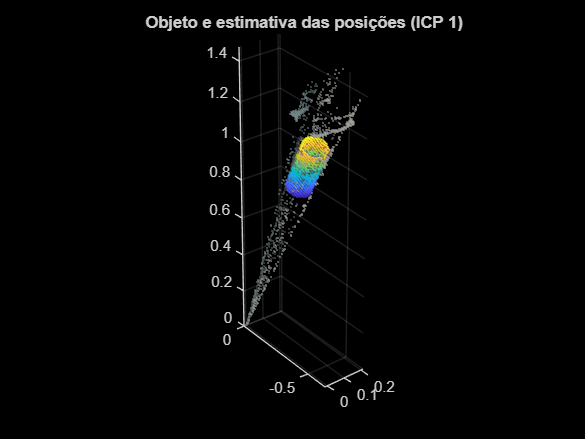


[tform, aligned, rmse] = pcregistericp(PcModeloT, PcObjectICP, ...
'Metric', 'planeToPlane', ...
'InlierDistance', Indist);

Tmatrix = tform;
Tmodel = aligned;

figure;
hold on;
grid on;
pcshow(PtCloudObj1);
pcshow(Tmodel);
title("Objeto e estimativa das posições (ICP 1)")
hold off;

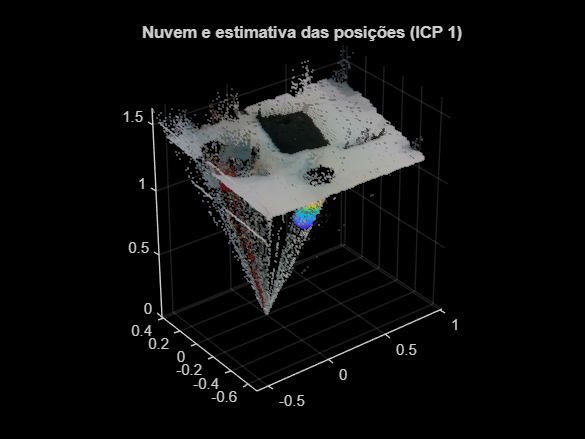


figure;
hold on;
grid on;
pcshow(ptCloud);
pcshow(Tmodel);
title("Nuvem e estimativa das posições (ICP 1)")
hold off;

rmse

rmse = 0.0341

**7. ICP (Translado no ICP)**

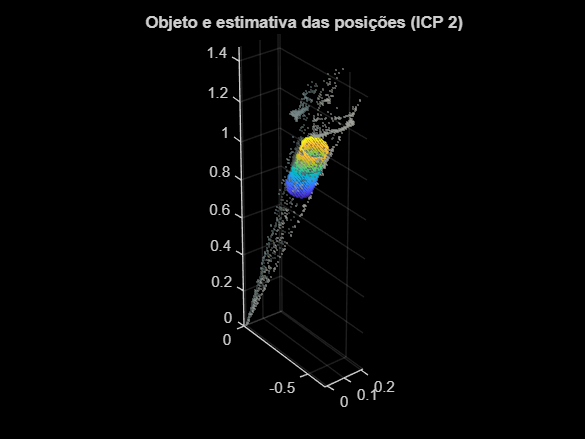

[tform, aligned, rmse] = pcregistericp(PcModeloICP, PcObjectICP, ...
'InitialTransform', initTform, ...
'Metric', 'planeToPlane', ...
'InlierDistance', Indist);

Tmatrix = tform;
Tmodel = aligned;

figure;
hold on;
grid on;
pcshow(PtCloudObj1);
pcshow(Tmodel);
title("Objeto e estimativa das posições (ICP 2)")
hold off;

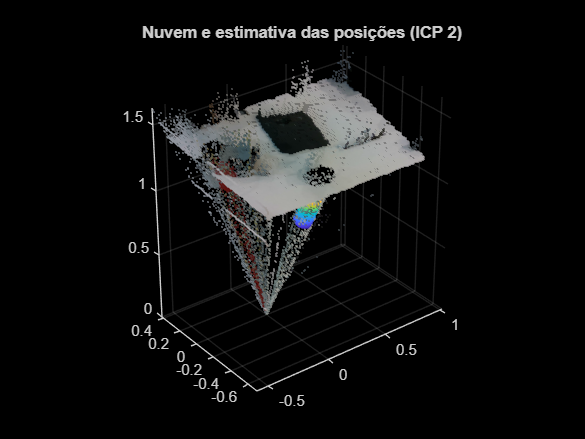


figure;
hold on;
grid on;
pcshow(ptCloud);
pcshow(Tmodel);
title("Nuvem e estimativa das posições (ICP 2)")
hold off;

rmse

rmse = 0.0342

## **Cubes!**

Identificação da orientação dos cubos com base em cores

**Setup Imagens de Cubos**

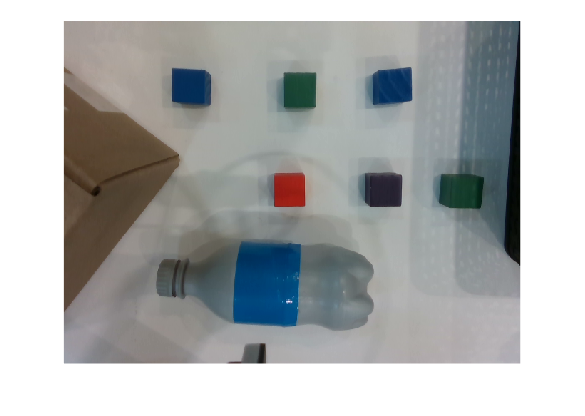

colorImage = imread("3.png"); %COR
imshow(colorImage);

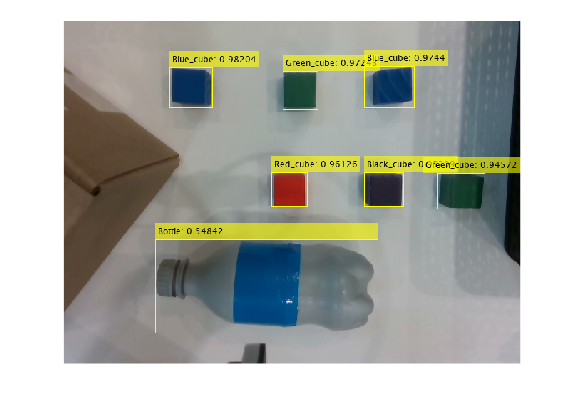


[bboxes, scores, labels] = detect(Detector, colorImage);

%Threshold de overlap
[bboxes, scores, selectedIdx] = selectStrongestBbox(bboxes, scores, ...
    'OverlapThreshold', 0.5);
labels = labels(selectedIdx);

labelsWithScores = string(labels) + ": " + string(scores);
imTested = insertObjectAnnotation(colorImage, "rectangle", bboxes, labelsWithScores);
imshow(imTested);

**Color Theory**

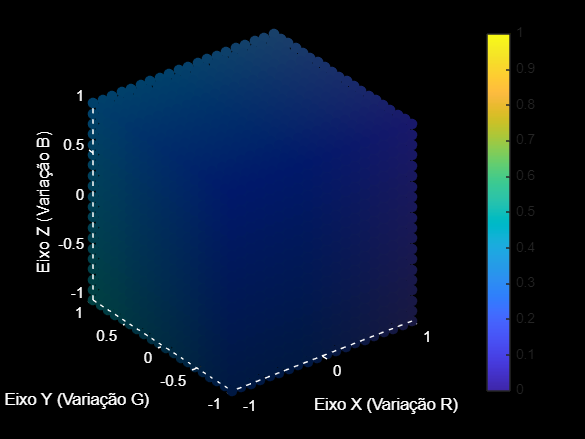

function colorPlot(central_rgb,n_pontos,variacao)

    [x, y, z] = meshgrid(linspace(-1, 1, n_pontos));
    
    % Normalizar as coordenadas para a variação de cor
    r = central_rgb(1) + x * variacao * n_pontos/2;
    g = central_rgb(2) + y * variacao * n_pontos/2;
    b = central_rgb(3) + z * variacao * n_pontos/2;
    
    % Garantir que os valores RGB estejam entre 0 e 255
    r = max(0, min(255, r));
    g = max(0, min(255, g));
    b = max(0, min(255, b));
    
    % Preparar cores (normalizadas para [0, 1])
    cores = zeros(n_pontos, n_pontos, n_pontos, 3);
    cores(:, :, :, 1) = r / 255; % Componente R
    cores(:, :, :, 2) = g / 255; % Componente G
    cores(:, :, :, 3) = b / 255; % Componente B
    
    % Plotar os pontos 3D com cores RGB
    figure;
    scatter3(x(:), y(:), z(:), 50, reshape(cores, [], 3), 'filled');
    xlabel('Eixo X (Variação R)');
    ylabel('Eixo Y (Variação G)');
    zlabel('Eixo Z (Variação B)');
    colorbar;
    axis equal;
    grid on;
    
    set(gcf, 'Color', 'k');       % Fundo da figura preto
    set(gca, 'Color', 'k', ...    % Fundo dos eixos preto
             'XColor', 'w', ...   % Eixo X branco
             'YColor', 'w', ...   % Eixo Y branco
             'ZColor', 'w');      % Eixo Z branco
end

blue = [4,44,86];
green = [26,69,51];
red = [152,30,20];
black = [39,33,48];
mesa = [165,169,164];

num = 20;
var = 2;

colorPlot(blue,num,var);

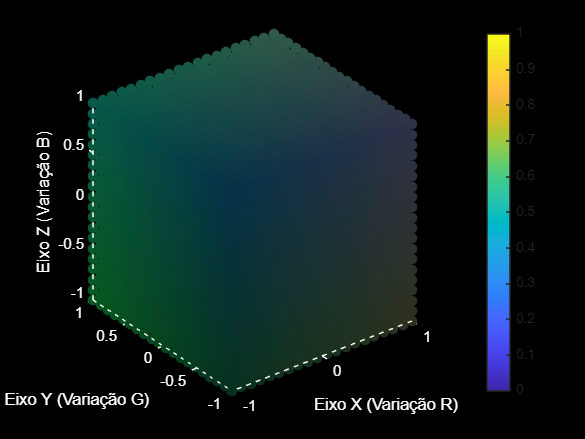

colorPlot(green,num,var);

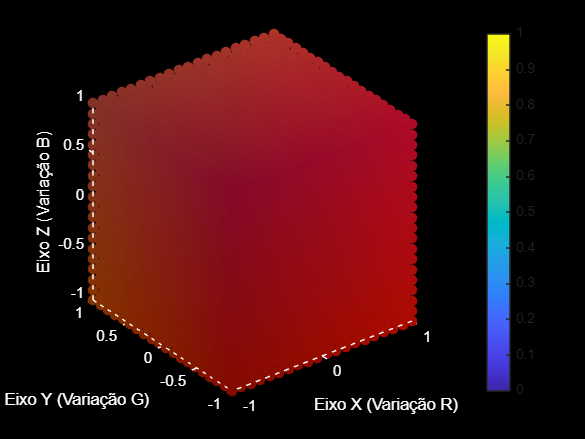

colorPlot(red,num,var);

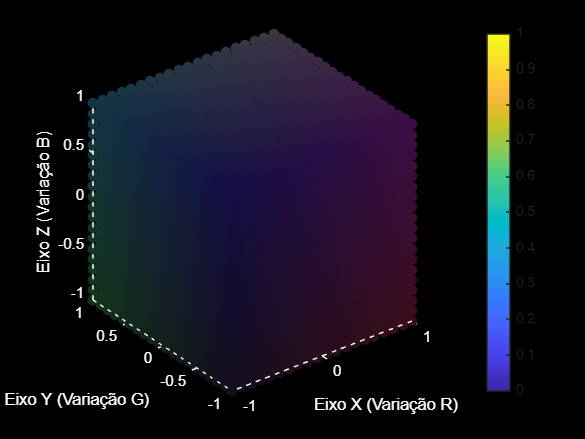

colorPlot(black,num,var);

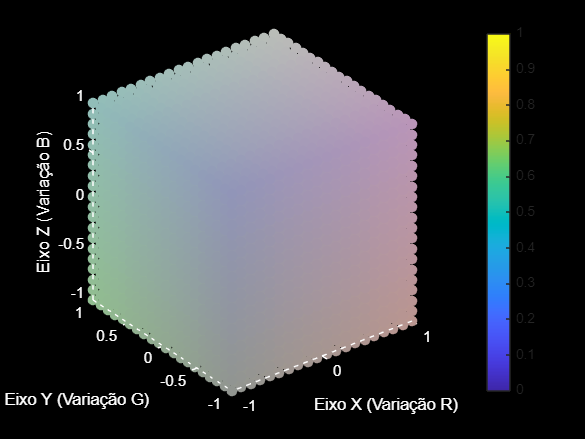

colorPlot(mesa,num,var);

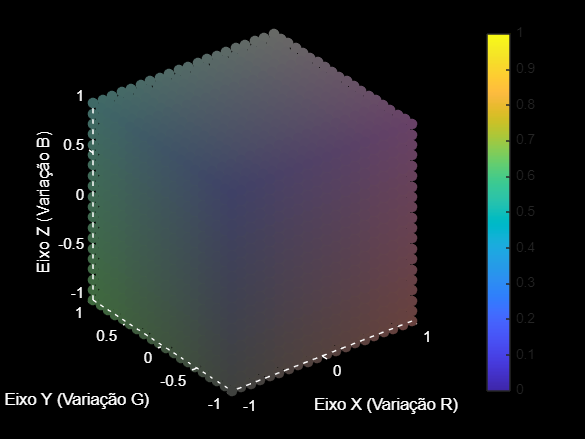

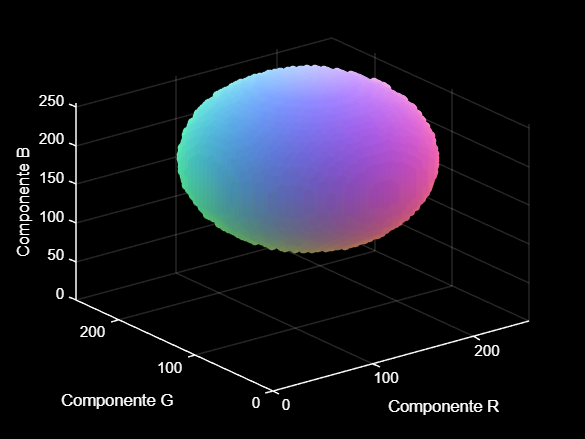


hsv_cor = rgb2hsv(mesa/255);
hsv_cor(3) = hsv_cor(3) * 0.5;
mesaEsc = round(hsv2rgb(hsv_cor) * 255);

colorPlot(mesaEsc,num,var); 

idx = (labels == "Green_cube")|(labels == "Red_cube")|(labels == "Black_cube")|(labels == "Blue_cube")

idx = 6×1 logical array
   1
   1
   1
   1
   1
   1


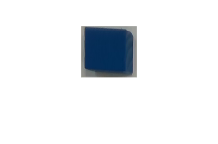

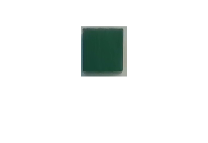

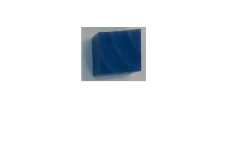

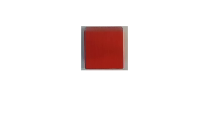

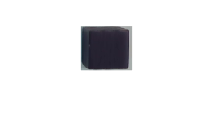

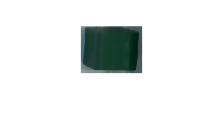


bboxes = bboxes(idx,:);
scores = scores(idx);
labels = labels(idx);

recorte = {};
for k = 1:numel(scores)
    recorte{k} = imcrop(colorImage, bboxes(k,:));
    figure;
    imshow(recorte{k});
end 

[R,G,B] = recorte{1}(1,2,:) 

Insufficient number of outputs from right hand side of equal sign to satisfy assignment.